### **3.2.1 Tank as a transfer funcion**

s = tf('s');
sys = 1/s;

### **3.2.2 Computing a step response**

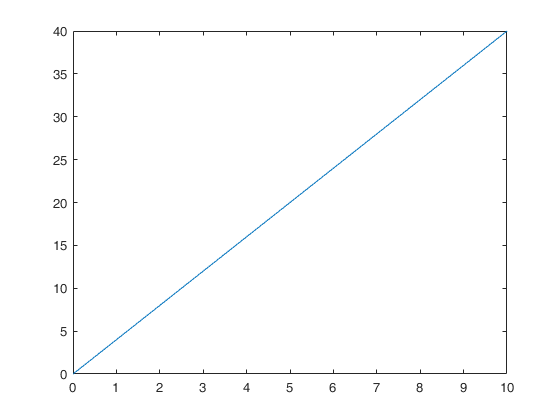

opt = stepDataOptions('StepAmplitude',4);
[y,t] = step(sys, opt);
plot(t,y)
xlim([0 10])
ylim([0 40])

### **3.2.3 Building the step response using a 'for loop'**

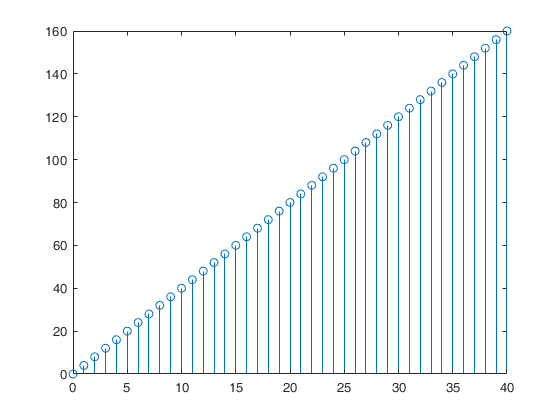

q_in = 5;
q_out = 1;
q = q_in-q_out;
v(1) = 0;
for i= 1:1:40
    v(i+1) = v(i)+q;
    
end
stem([0:1:40],v)

### 4.5 Exporting data from Simulink to Matlab

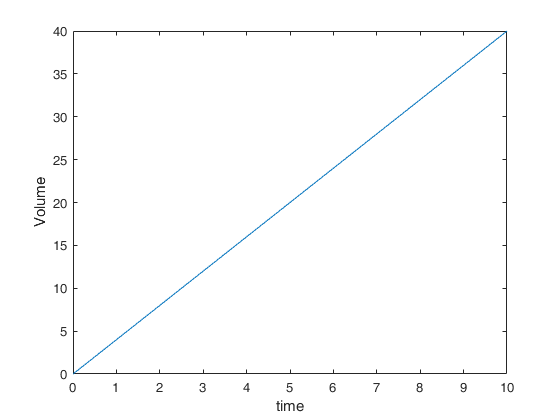

plot(out.V.time, out.V.signals.values)
xlabel("time")
ylabel("Volume")